# Non-parametric Estimation: Welch Method (Current Input)

Add a function to control the format plot style setting.

## Loading Data

clc
clear
close all

load data/sysid_power_case1.mat

## Data Visualization

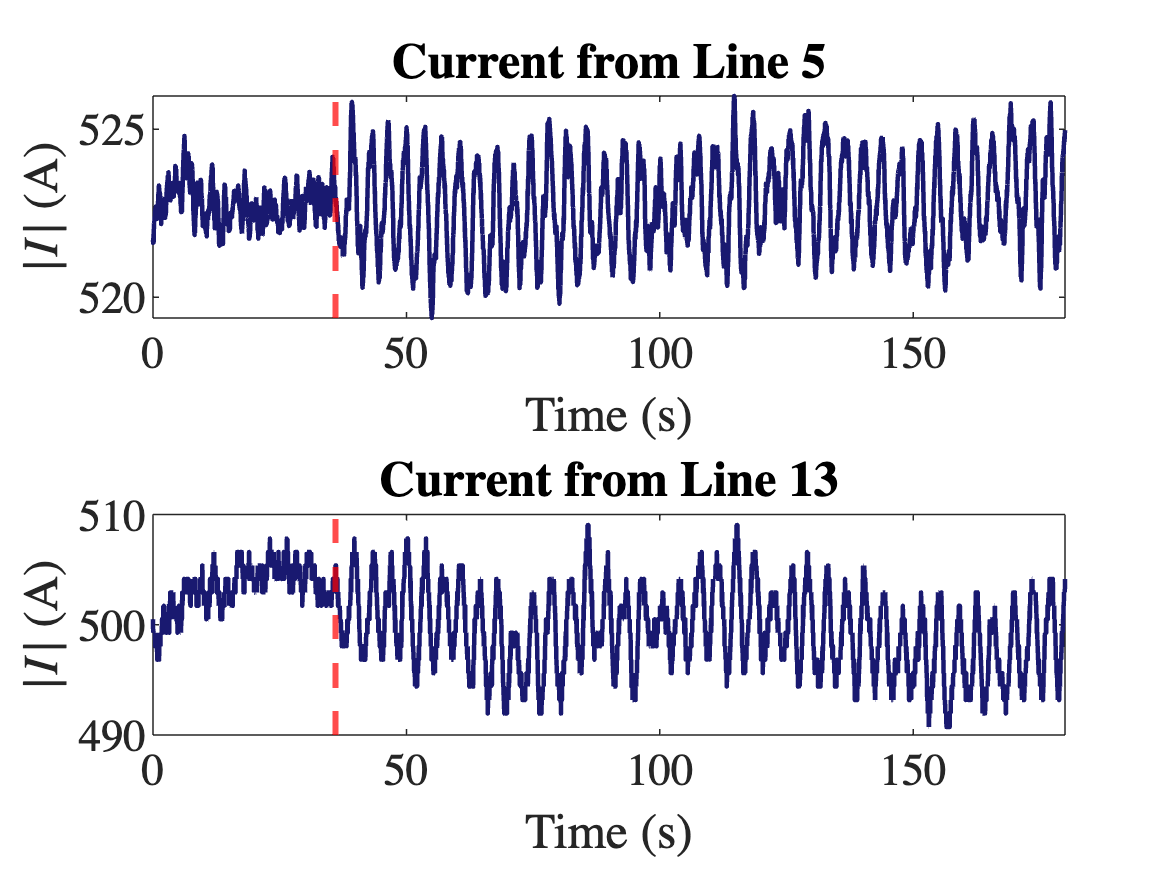

width = 8;
height = 6;

fig = figure('Renderer', 'opengl', 'Position', [10 10 width*100 height*100]);
set(0, 'DefaultLineLineWidth', 1.5);
set(0,'DefaultAxesFontSize', 18)
set(0,'DefaultTextFontSize', 18)
set(0, 'DefaultTextFontName', 'Times')
set(0, 'DefaultAxesFontName', 'Times')

subplot(211)
plot(time, Im(:, 5), 'color', '#191970')
xlim([0, max(time)])
title('Current from Line 5')
xlabel('Time (s)')
ylabel('$\vert I \vert$ (A)', 'interpreter', 'latex')
xline(t_event, 'color', 'red', 'linewidth', 2, 'linestyle', '--')

subplot(212)
plot(time, Im(:, 13),  'color', '#191970')
xlim([0, max(time)])
title('Current from Line 13')
xlabel('Time (s)')
ylabel('$\vert I \vert$ (A)', 'interpreter', 'latex')
xline(t_event, 'color', 'red', 'linewidth', 2, 'linestyle', '--')

### Visualizing Signal During Event

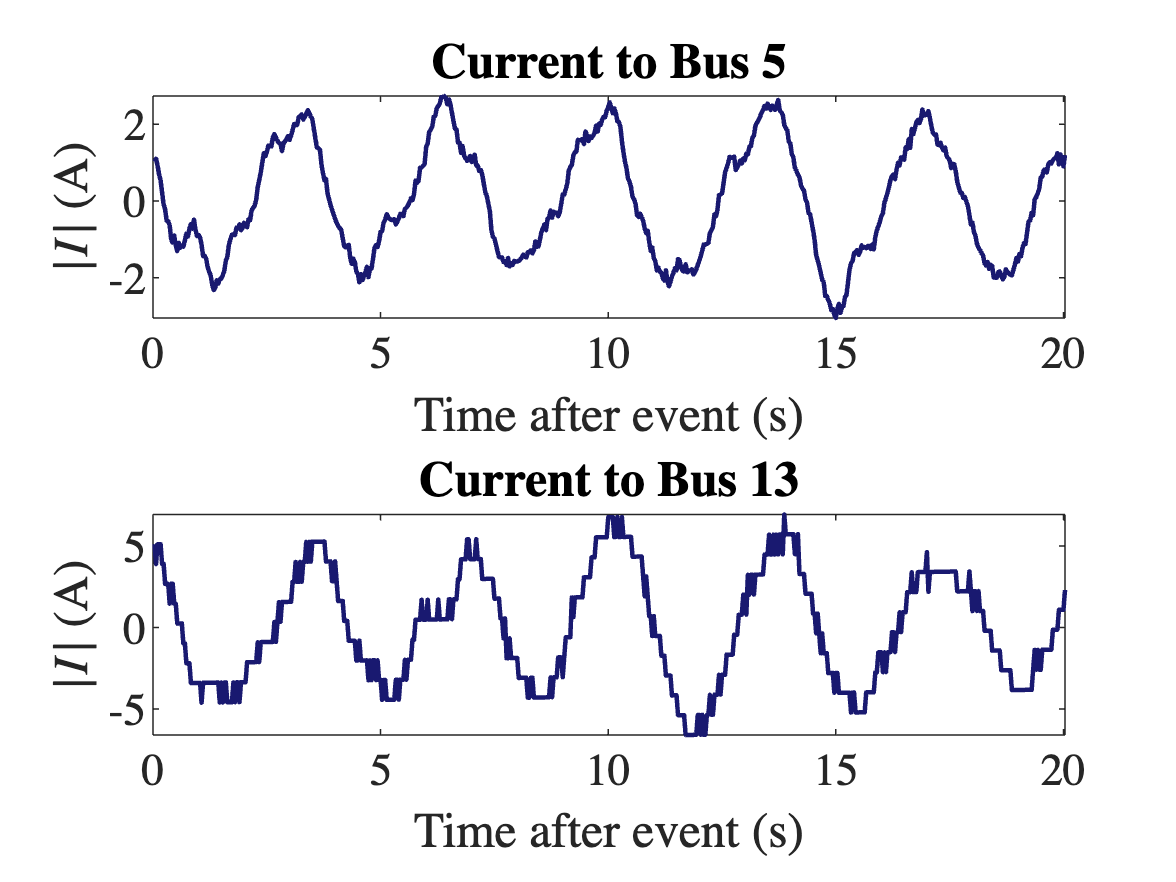

y1 = Im(1202:1802, 5);
N1 = size(y1, 1);
t1 = ts:ts:length(y1)*ts;

y2 = Im(1202:1802,13);
N2 = size(y2, 1);
t2 = ts:ts:length(y2)*ts;

y1 = detrend(y1);
y2 = detrend(y2);

width = 8;
height = 6;

fig = figure('Renderer', 'opengl', 'Position', [10 10 width*100 height*100]);
set(0, 'DefaultLineLineWidth', 1.5);
set(0,'DefaultAxesFontSize', 18)
set(0,'DefaultTextFontSize', 18)
set(0, 'DefaultTextFontName', 'Times')
set(0, 'DefaultAxesFontName', 'Times')

subplot(211)
plot(t1, y1, 'color', '#191970')
xlim([0, max(t1)])
xlabel('Time after event (s)')
ylabel('$\vert I \vert$ (A)', 'interpreter', 'latex')
title('Current to Bus 5')

subplot(212)
plot(t2, y2, 'color', '#191970')
xlim([0, max(t2)])
xlabel('Time after event (s)')
ylabel('$\vert I \vert$ (A)', 'interpreter', 'latex')
title('Current to Bus 13')

### Autocorrelation Plot

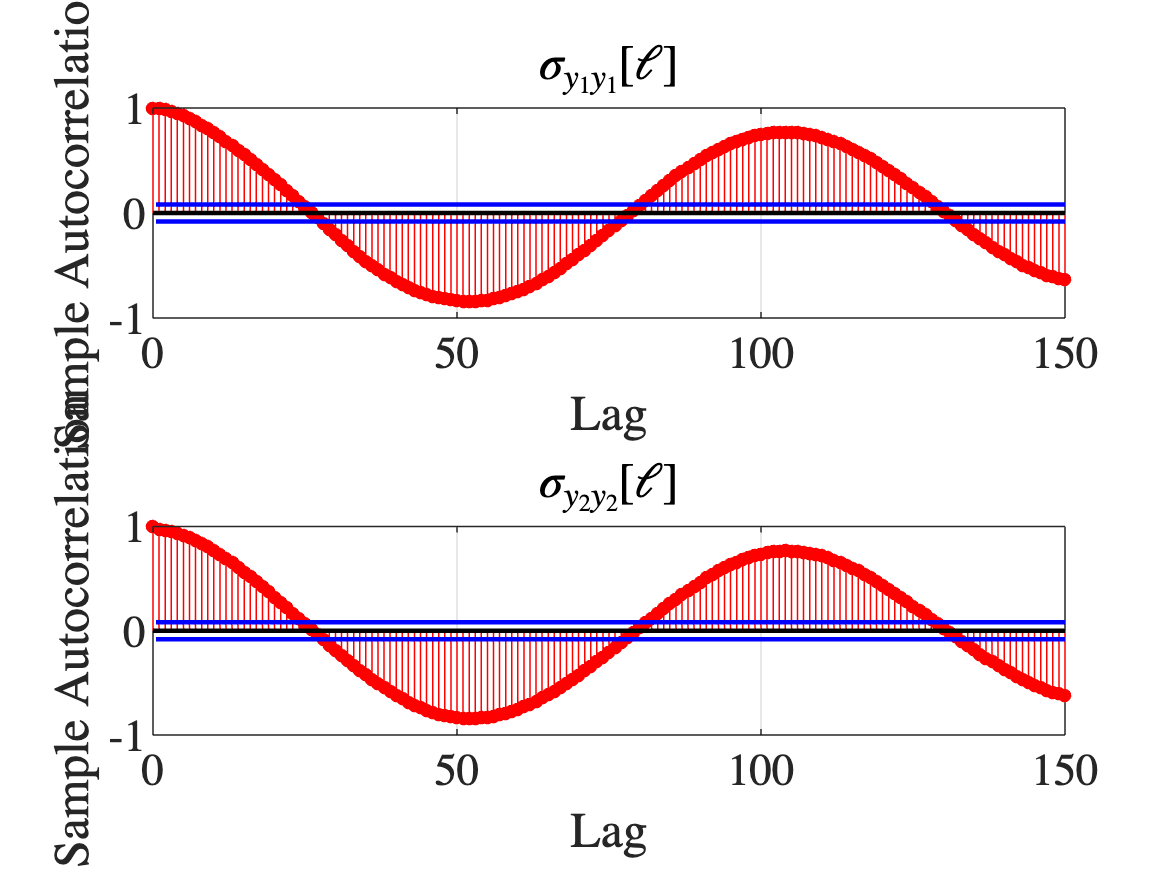

width = 8;
height = 6;

fig = figure('Renderer', 'opengl', 'Position', [10 10 width*100 height*100]);
set(0, 'DefaultLineLineWidth', 1.5);
set(0,'DefaultAxesFontSize', 18)
set(0,'DefaultTextFontSize', 18)
set(0, 'DefaultTextFontName', 'Times')
set(0, 'DefaultAxesFontName', 'Times')

subplot(211)
autocorr(y1, 'NumLags', round(N1/4));
title('$\sigma_{y_1y_1}\left[\ell\right]$', 'interpreter', 'latex')

subplot(212)
autocorr(y2, 'NumLags', round(N2/4));
title('$\sigma_{y_2y_2}\left[\ell\right]$', 'interpreter', 'latex')

## PSD Estimation

Change to have a control to vary the Nfft number.

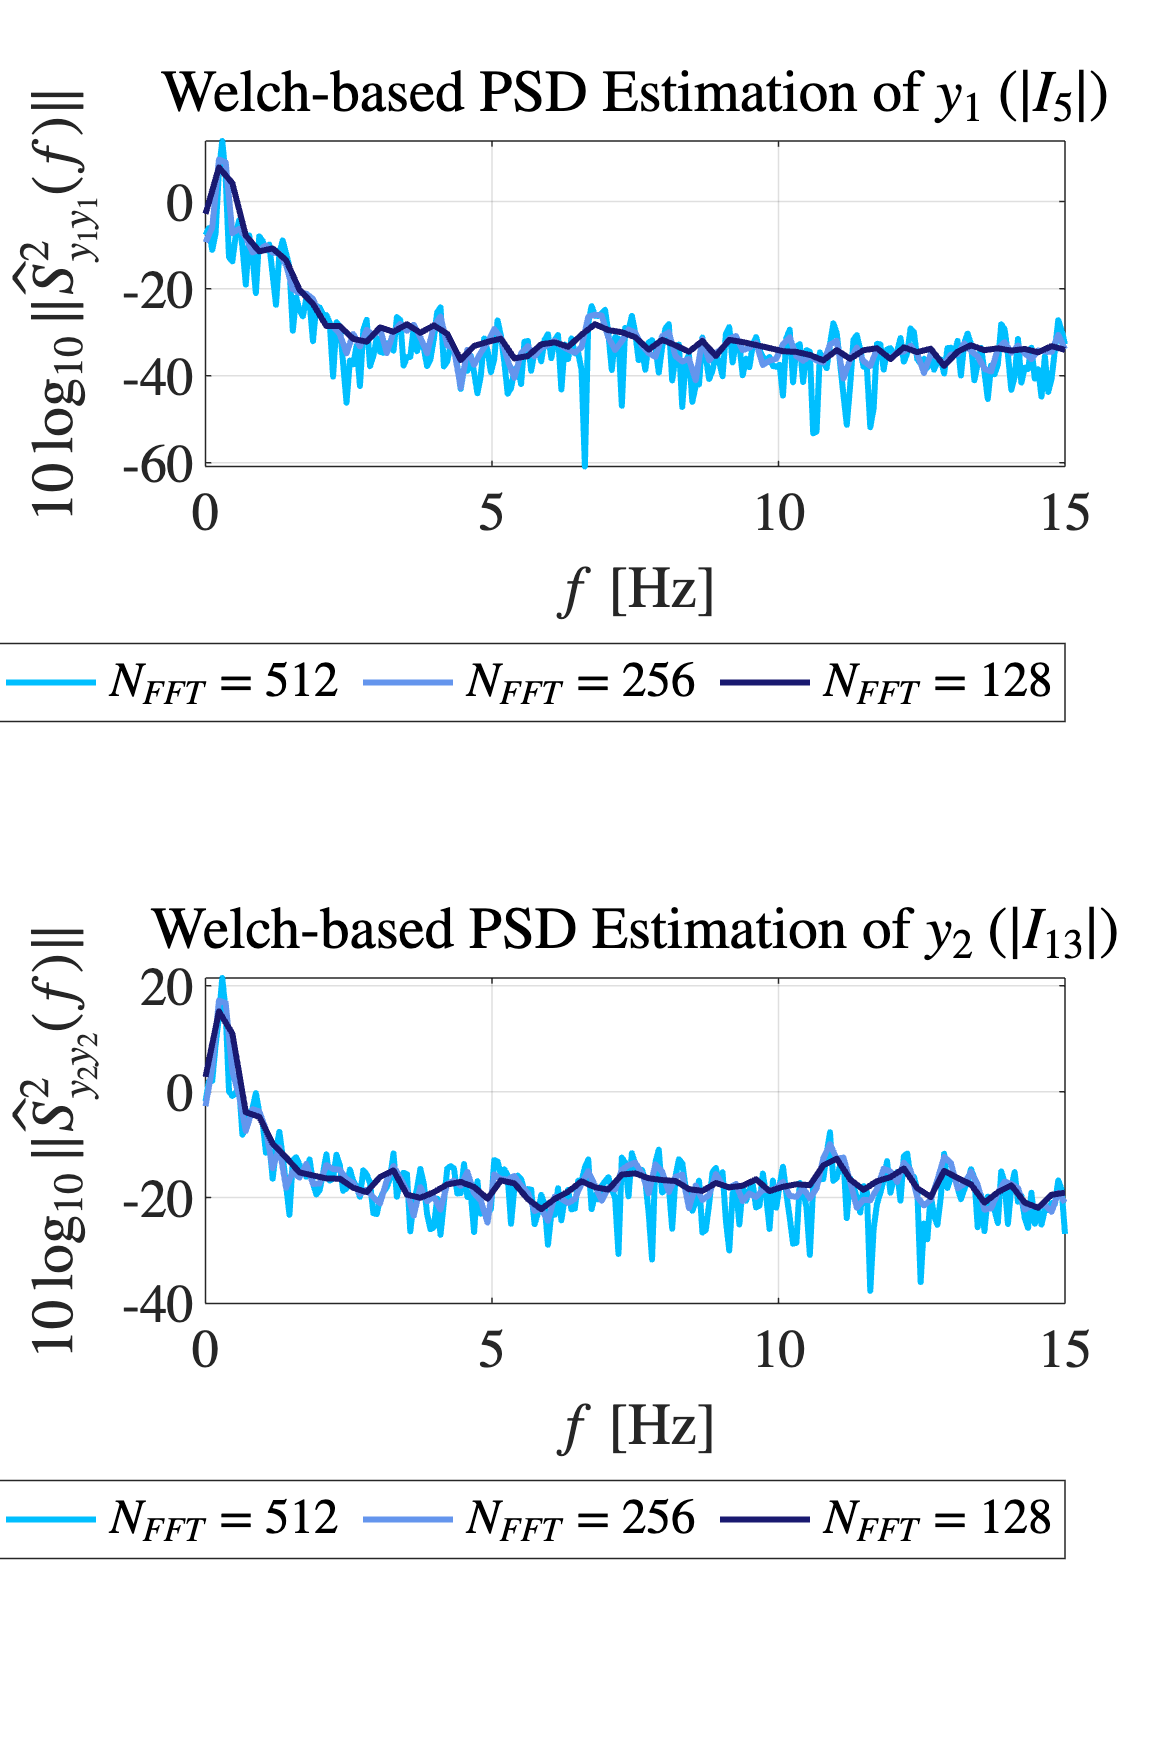

% Window-size
Nfft = [128, 256, 512];
linestyle = {'-', '-', '-', '-'};
color = {'#191970', '#6495ED', '#00BFFF', '#ADD8E6'};

width = 8;
height = 12;

fig = figure('Renderer', 'opengl', 'Position', [10 10 width*100 height*100]);
set(0, 'DefaultLineLineWidth', 2);
set(0,'DefaultAxesFontSize', 18)
set(0,'DefaultTextFontSize', 18)
set(0, 'DefaultTextFontName', 'Times')
set(0, 'DefaultAxesFontName', 'Times')

for i=length(Nfft):-1:1

subplot(211)
% PSD estimation using Welch method
[Pyy1, f] = pwelch(y1, Nfft(i), [], Nfft(i), fs);
plot(f, 10*log10(Pyy1), linestyle{i}, 'color', color{i}, 'DisplayName', ...
    "$N_{FFT}$ = " + string(Nfft(i)))
xlim([0, fs/2])
hold on

if i==1
    grid on
    xlabel('$f$ [Hz]', 'interpreter', 'latex');
    ylabel('$10 \log_{10}\Vert \hat{S}_{y_1y_1}^2(f)\Vert$', ...
        'Interpreter', 'latex');
    title('Welch-based PSD Estimation of $y_1$ ($|I_{5}|$)', ...
        'Interpreter','latex');
    lgd = legend('interpreter', 'latex');
    lgd.NumColumns = 4;
    lgd.Location = 'southoutside';
end

subplot(212)
[Pyy2, f] = pwelch(y2, Nfft(i), [], Nfft(i), fs);
plot(f, 10*log10(Pyy2), linestyle{i}, 'color', color{i}, 'DisplayName', ...
    "$N_{FFT}$ = " + string(Nfft(i)))
xlim([0, fs/2])
hold on

if i==1
    grid on
    xlabel('$f$ [Hz]', 'interpreter', 'latex');
    ylabel('$10 \log_{10}\Vert \hat{S}_{y_2y_2}^2(f)\Vert$', ...
        'Interpreter', 'latex');
    title('Welch-based PSD Estimation of $y_2$ ($|I_{13}|$)', ...
        'Interpreter','latex');
    lgd = legend('interpreter', 'latex');
    lgd.NumColumns = 4;
    lgd.Location = 'southoutside';
end

end